clear all
close all
clc

% load temp.mat % high res
load temp2.mat % low res
 
close all

net

net =   DCMicrogrid with properties:

         DGs: [1×4 DG]
       Lines: [1×4 TransmissionLine]
           N: 4
           M: 4
           G: []
           A: [8×8 double]
        BBar: [8×8 double]
           E: [8×4 double]
           B: [8×4 double]
           D: [8×4 double]
        DBar: [8×4 double]
         u_s: [4×1 double]
        wBar: [4×1 double]
           Y: [4×4 double]
        YBar: [4×4 double]
         x_s: [8×1 double]
          ss: [1×1 struct]
           K: []
     commAdj: [4×4 double]
           z: [4×1 double]
         K_I: []
      QBar_w: [24×24 double]
      E_perm: [24×24 double]
          Ts: 1.0000e-04
    u_G_Hold: [4×1 double]
      I_Hold: []


DG = net.DGs(2)

DG =   DG with properties:

           id: 2
            L: 9.9998e-04
            C: 9.1319e-04
           Rf: 0.0952
         YBar: 2.0912
           RL: 7.1517
         Ibar: 6.3568
    iload_fun: @(t)0
          u_s: 43.9436
            K: [0.1236 0.2323]
            x: [2×1 double]
        noise: [1×1 struct]
          pos: [2.2394 0.3080]
        color: [0 0.4500 0.7400]
            A: [2×2 double]
            B: [2×1 double]
            E: [2×1 double]
         BBar: [2×2 double]
       Vrated: 48
       Irated: 22.3750
          x_s: [2×1 double]
          I_s: -0.9479
           nu: -3.7110
          rho: 8.6106e-10
       xTilde: [2×100 double]
    xTildeBar: [2×100 double]
       yTilde: [2×100 double]
       uTilde: [2×100 double]
       wTilde: [2×100 double]
          Q_w: [102×102 double]
       QBar_w: [6×6 double]
           Kc: []
           Kd: []
           Ts: 1.0000e-04
     u_L_Hold: 9.4648e-08



DG.x

ans =    46.5415
    9.6144


DG.x_s

ans =    46.4811
    9.8470


xTild = DG.x - DG.x_s

xTild =     0.0603
   -0.2326


DG.xTilde(:,end)

ans =     0.0891
   -0.2228



xData = DG.xTilde + DG.x_s

xData =    46.1737   46.3707   46.5716   46.7725   46.9695   47.1586   47.3364   47.5002   47.6480   47.7782   47.8899   47.9824   48.0557   48.1100   48.1455   48.1631   48.1634   48.1475   48.1163   48.0709   48.0127   47.9428   47.8625   47.7730   47.6758   47.5720   47.4630   47.3500   47.2342   47.1169   46.9991   46.8820   46.7666   46.6538   46.5446   46.4397   46.3400   46.2460   46.1584   46.0776   46.0041   45.9383   45.8803   45.8305   45.7887   45.7552   45.7298   45.7125   45.7029   45.7010
   12.0975   12.1283   12.1454   12.1468   12.1313   12.0985   12.0485   11.9822   11.9004   11.8045   11.6960   11.5765   11.4476   11.3111   11.1687   11.0221   10.8728   10.7224   10.5726   10.4245   10.2796   10.1391   10.0040    9.8753    9.7540    9.6407    9.5361    9.4408    9.3551    9.2795    9.2141    9.1590    9.1142    9.0796    9.0552    9.0405    9.0354    9.0394    9.0520    9.0727    9.1010    9.1362    9.1778    9.2249    9.2770    9.3334    9.3933    9.4560    9.5208 

xDataBar = DG.xTildeBar + DG.x_s

xDataBar =    46.3707   46.5716   46.7725   46.9695   47.1586   47.3364   47.5002   47.6480   47.7782   47.8899   47.9824   48.0557   48.1100   48.1455   48.1631   48.1634   48.1475   48.1163   48.0709   48.0127   47.9428   47.8625   47.7730   47.6758   47.5720   47.4630   47.3500   47.2342   47.1169   46.9991   46.8820   46.7666   46.6538   46.5446   46.4397   46.3400   46.2460   46.1584   46.0776   46.0041   45.9383   45.8803   45.8305   45.7887   45.7552   45.7298   45.7125   45.7029   45.7010   45.7064
   12.1283   12.1454   12.1468   12.1313   12.0985   12.0485   11.9822   11.9004   11.8045   11.6960   11.5765   11.4476   11.3111   11.1687   11.0221   10.8728   10.7224   10.5726   10.4245   10.2796   10.1391   10.0040    9.8753    9.7540    9.6407    9.5361    9.4408    9.3551    9.2795    9.2141    9.1590    9.1142    9.0796    9.0552    9.0405    9.0354    9.0394    9.0520    9.0727    9.1010    9.1362    9.1778    9.2249    9.2770    9.3334    9.3933    9.4560    9.5208    9.58

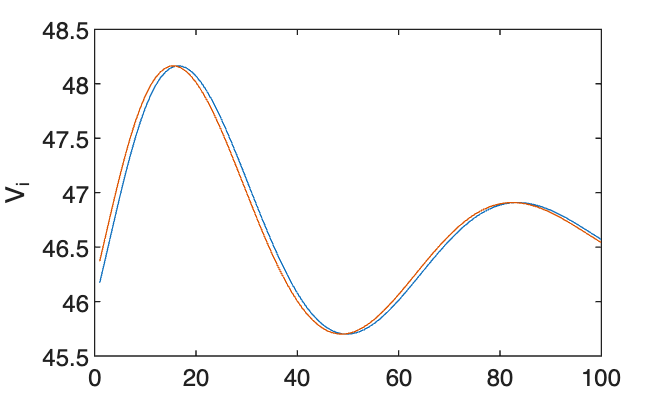

figure
plot(xData(1,:)); hold on; plot(xDataBar(1,:))
ylabel('V_i')

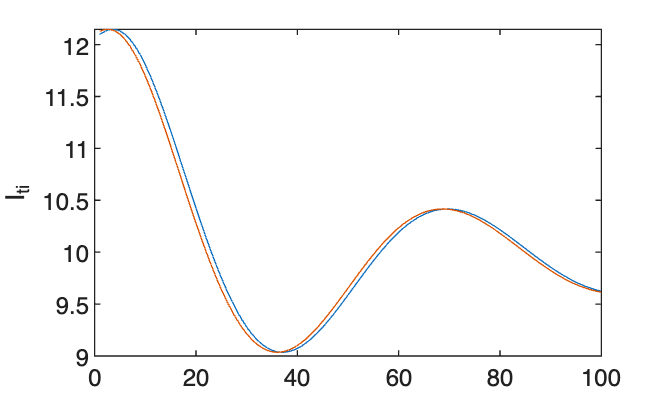

figure
plot(xData(2,:)); hold on; plot(xDataBar(2,:))
ylabel('I_{ti}')


u_s = [DG.I_s; DG.u_s]

u_s =    -0.9479
   43.9436


DG.uTilde(:,end)

ans =    -0.0448
   -0.0441



uData = DG.uTilde + u_s

uData =     0.3123    0.2714    0.2419    0.2286    0.2307    0.2445    0.2653    0.2885    0.3104    0.3276    0.3380    0.3399    0.3325    0.3154    0.2886    0.2525    0.2079    0.1554    0.0961    0.0309   -0.0392   -0.1131   -0.1898   -0.2683   -0.3477   -0.4270   -0.5056   -0.5826   -0.6574   -0.7292   -0.7977   -0.8623   -0.9225   -0.9781   -1.0288   -1.0743   -1.1145   -1.1493   -1.1788   -1.2028   -1.2215   -1.2349   -1.2433   -1.2468   -1.2457   -1.2402   -1.2317   -1.2172   -1.2003   -1.1804
   44.1839   44.2464   44.2858   44.3084   44.3184   44.3190   44.3125   44.3005   44.2843   44.2647   44.2425   44.2182   44.1924   44.1654   44.1377   44.1094   44.0809   44.0526   44.0245   43.9969   43.9701   43.9443   43.9196   43.8962   43.8741   43.8537   43.8349   43.8179   43.8027   43.7893   43.7779   43.7684   43.7609   43.7553   43.7516   43.7497   43.7496   43.7513   43.7545   43.7593   43.7656   43.7731   43.7819   43.7918   43.8025   43.8141   43.8252   43.8393   43.8525 

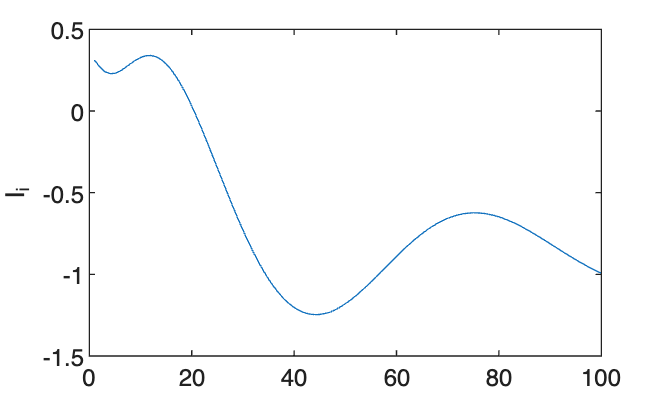

figure
plot(uData(1,:))
ylabel('I_i')

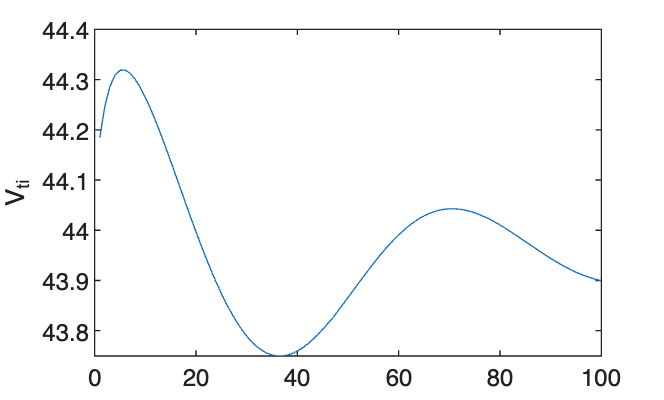

figure
plot(uData(2,:))
ylabel('V_{ti}')


wData = DG.wTilde

wData =     0.0029    0.0014   -0.0006   -0.0027   -0.0046   -0.0061   -0.0074   -0.0083   -0.0090   -0.0094   -0.0096   -0.0096   -0.0095   -0.0092   -0.0089   -0.0085   -0.0080   -0.0074   -0.0069   -0.0063   -0.0056   -0.0050   -0.0043   -0.0037   -0.0030   -0.0024   -0.0018   -0.0012   -0.0006   -0.0000    0.0005    0.0010    0.0015    0.0019    0.0023    0.0027    0.0030    0.0033    0.0035    0.0037    0.0039    0.0040    0.0041    0.0041    0.0041    0.0041    0.0039    0.0039    0.0038    0.0036
   -0.0059   -0.0073   -0.0081   -0.0086   -0.0087   -0.0085   -0.0081   -0.0075   -0.0068   -0.0061   -0.0052   -0.0044   -0.0035   -0.0027   -0.0018   -0.0010   -0.0003    0.0005    0.0011    0.0018    0.0024    0.0029    0.0034    0.0038    0.0041    0.0045    0.0047    0.0049    0.0050    0.0051    0.0052    0.0052    0.0051    0.0050    0.0049    0.0047    0.0045    0.0042    0.0040    0.0037    0.0034    0.0030    0.0027    0.0024    0.0020    0.0016    0.0014    0.0009    0.0006 

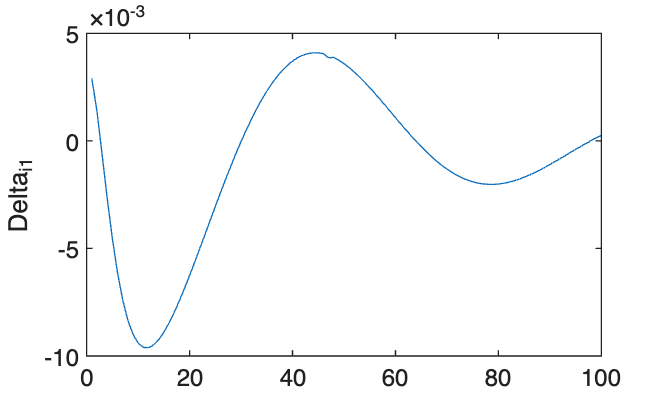

figure
plot(wData(1,:))
ylabel('Delta_{i1}')

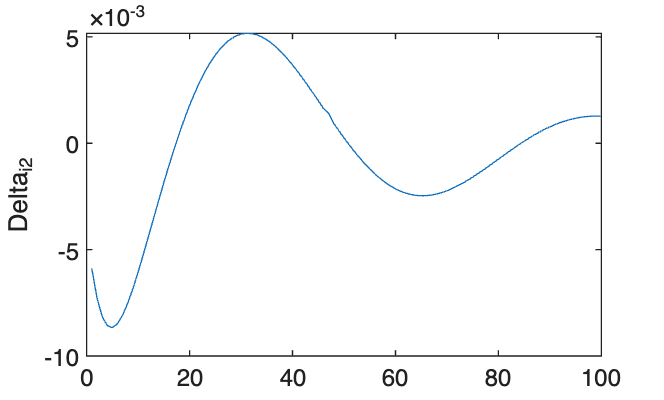

figure
plot(wData(2,:))
ylabel('Delta_{i2}')


Ts = DG.Ts

Ts = 1.0000e-04

A = DG.A

A = 1.0e+03 *

   -0.1800    1.4511
   -0.9304   -0.0709


B = DG.BBar

B = 1.0e+03 *

   -1.0951         0
         0    1.0000




wTilde = DG.xTildeBar - ((eye(2)+Ts*A)*DG.xTilde + Ts*B*DG.uTilde)

wTilde =     0.0029    0.0014   -0.0006   -0.0027   -0.0046   -0.0061   -0.0074   -0.0083   -0.0090   -0.0094   -0.0096   -0.0096   -0.0095   -0.0092   -0.0089   -0.0085   -0.0080   -0.0074   -0.0069   -0.0063   -0.0056   -0.0050   -0.0043   -0.0037   -0.0030   -0.0024   -0.0018   -0.0012   -0.0006   -0.0000    0.0005    0.0010    0.0015    0.0019    0.0023    0.0027    0.0030    0.0033    0.0035    0.0037    0.0039    0.0040    0.0041    0.0041    0.0041    0.0041    0.0039    0.0039    0.0038    0.0036
   -0.0059   -0.0073   -0.0081   -0.0086   -0.0087   -0.0085   -0.0081   -0.0075   -0.0068   -0.0061   -0.0052   -0.0044   -0.0035   -0.0027   -0.0018   -0.0010   -0.0003    0.0005    0.0011    0.0018    0.0024    0.0029    0.0034    0.0038    0.0041    0.0045    0.0047    0.0049    0.0050    0.0051    0.0052    0.0052    0.0051    0.0050    0.0049    0.0047    0.0045    0.0042    0.0040    0.0037    0.0034    0.0030    0.0027    0.0024    0.0020    0.0016    0.0014    0.0009    0.0006

% discError = obj.DGs(k).xTildeBar - ( (eye(2) + Ts*obj.DGs(k).A)*obj.DGs(k).xTilde ...
                                        % + Ts*obj.DGs(k).BBar*obj.DGs(k).uTilde);
wData

wData =     0.0029    0.0014   -0.0006   -0.0027   -0.0046   -0.0061   -0.0074   -0.0083   -0.0090   -0.0094   -0.0096   -0.0096   -0.0095   -0.0092   -0.0089   -0.0085   -0.0080   -0.0074   -0.0069   -0.0063   -0.0056   -0.0050   -0.0043   -0.0037   -0.0030   -0.0024   -0.0018   -0.0012   -0.0006   -0.0000    0.0005    0.0010    0.0015    0.0019    0.0023    0.0027    0.0030    0.0033    0.0035    0.0037    0.0039    0.0040    0.0041    0.0041    0.0041    0.0041    0.0039    0.0039    0.0038    0.0036
   -0.0059   -0.0073   -0.0081   -0.0086   -0.0087   -0.0085   -0.0081   -0.0075   -0.0068   -0.0061   -0.0052   -0.0044   -0.0035   -0.0027   -0.0018   -0.0010   -0.0003    0.0005    0.0011    0.0018    0.0024    0.0029    0.0034    0.0038    0.0041    0.0045    0.0047    0.0049    0.0050    0.0051    0.0052    0.0052    0.0051    0.0050    0.0049    0.0047    0.0045    0.0042    0.0040    0.0037    0.0034    0.0030    0.0027    0.0024    0.0020    0.0016    0.0014    0.0009    0.0006 

disp('Model Based Design')

DG 1


ans =     0.0048   -0.0096
   -0.0096    0.0277


XXt =    11.9559   -0.8491
   -0.8491    5.9172


DG 2


ans =     0.0025    0.0006
    0.0006    0.0022


XXt =    58.3086   35.4099
   35.4099   76.5334


DG 3


ans =     0.0030   -0.0001
   -0.0001    0.0020


XXt =    30.9211   -0.5026
   -0.5026   42.1123


DG 4


ans =     0.0053   -0.0013
   -0.0013    0.0016


XXt =    31.7530   -8.8946
   -8.8946   20.7365


ans =   -58.3060  -35.4093   58.0479   40.5182   39.1887    6.2626
  -35.4093  -76.5312   29.5551   78.8080   43.9875   13.0663
   58.0479   29.5551  -58.3995  -34.7319  -37.1332   -5.2269
   40.5182   78.8080  -34.7319  -81.5441  -47.1725  -13.4625
   39.1887   43.9875  -37.1332  -47.1725  -35.7965   -7.1281
    6.2626   13.0663   -5.2269  -13.4625   -7.1281   -2.3473


ans =     0.0025    0.0006         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0006    0.0022         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Model Based Design


DG.designLocalXiDissipative()

LVal = 1.0e-03 *

   -0.0000    0.0000
   -0.2164   -0.6003


PVal =     0.0010   -0.0000
   -0.0000    0.0010


xBar11Val = 0.9584

x22Val = -0.2962

k_crit =      0     6


minor_crit = 0.3860

eigs = 1.0e+03 *

  -0.4518 + 1.1265i
  -0.4518 - 1.1265i


Local Design Success!
(nu,rho)=(-3.2361,0.29615)K=[-0.21644,-0.60034]


ans = struct with fields:
    problem: 0
       info: 'Successfully solved '
          P: [2×2 double]
          L: [2×2 double]
         nu: -3.2361
        rho: 0.2962
          K: [-0.2164 -0.6003]


disp('Data-Driven Design')

Data-Driven Design


DG = net.DGs(4)

DG =   DG with properties:

           id: 4
            L: 0.0011
            C: 0.0011
           Rf: 0.0525
         YBar: 1.6431
           RL: 5.5709
         Ibar: 2.7126
    iload_fun: @(t)0
          u_s: 37.2851
            K: [0.0207 -5.0855]
            x: [2×1 double]
        noise: [1×1 struct]
          pos: [1.7877 -3.4236]
        color: [0 0.4500 0.7400]
            A: [2×2 double]
            B: [2×1 double]
            E: [2×1 double]
         BBar: [2×2 double]
       Vrated: 48
       Irated: 22.7500
          x_s: [2×1 double]
          I_s: 2.3055
           nu: -0.1565
          rho: 0.0128
       xTilde: []
    xTildeBar: []
       yTilde: []
       uTilde: []
       wTilde: []
          Q_w: []
       QBar_w: []
           Kc: []
           Kd: []
           Ts: []
     u_L_Hold: []


DG.designLocalXiDissipative_DataDriven()


net.codesign_DD_DRC(1e-4)

LVal = 1.0e-08 *

         0         0
    0.0983   -0.6935


PVal = 1.0e-08 *

    0.1052   -0.0350
   -0.0350    0.2361


lam1 = 1.8354e-06

lam2 = 2.2661e-07

k_crit =     11    11


minor_crit = -1.8849e-75

k_crit2 =     12    12


minor_crit2 = -2.7243e-88

eigs =     0.9343
    0.7296


Local Design Success at DG 1!
(nu,rho)=(-2.4,1.0595e-09), K=[-0.045878,-2.9438]


LVal = 1.0e-09 *

         0         0
    0.1878    0.2592


PVal = 1.0e-08 *

    0.1297    0.0118
    0.0118    0.1053


lam1 = 7.2080e-06

lam2 = 2.8501e-05

k_crit =     10    10


minor_crit = -1.1775e-64

k_crit2 =      0    16


minor_crit2 = 8.5416e-102

eigs =     1.0048
    1.0048


Local Design Success at DG 2!
(nu,rho)=(-3.711,8.6106e-10), K=[0.12358,0.23231]


LVal = 1.0e-09 *

         0         0
   -0.3462    0.0424


PVal = 1.0e-08 *

    0.1316   -0.0050
   -0.0050    0.1177


lam1 = 6.8368e-06

lam2 = 7.8873e-06

k_crit =     10    10


minor_crit = -2.6953e-63

k_crit2 =      0    16


minor_crit2 = 1.1353e-104

eigs =     0.9990
    0.9990


Local Design Success at DG 3!
(nu,rho)=(-4.4496,7.6795e-10), K=[-0.26204,0.025029]


LVal = 1.0e-08 *

         0         0
   -0.0433   -0.1103


PVal = 1.0e-09 *

    0.4394    0.0122
    0.0122    0.8440


lam1 = 5.9519e-06

lam2 = 2.7639e-05

k_crit =     11    11


minor_crit = -5.7684e-73

k_crit2 =     14    14


minor_crit2 = -1.8404e-87

eigs =     0.9385
    0.9385


Local Design Success at DG 4!
(nu,rho)=(-7.1165,4.8655e-10), K=[-0.9493,-1.2929]


QBar_w_disp =   -11.9511    0.8395   11.9400    0.3962   -2.8581   -3.3631         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.8395   -5.8895   -1.3419    8.0905    3.3322  -24.7205         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   11.9400   -1.3419  -12.0035    0.2864    2.7536    1.2710         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.3962    8.0905    0.2864  -11.2671   -4.2681   34.7107         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -2.8581    3.3322  

EQBarET_neg =    11.9511   -0.8395         0         0         0         0         0         0  -11.9400   -0.3962         0         0         0         0         0         0    2.8581    3.3631         0         0         0         0         0         0
   -0.8395    5.8895         0         0         0         0         0         0    1.3419   -8.0905         0         0         0         0         0         0   -3.3322   24.7205         0         0         0         0         0         0
         0         0   58.3060   35.4093         0         0         0         0         0         0  -58.0479  -40.5182         0         0         0         0         0         0  -39.1887   -6.2626         0         0         0         0
         0         0   35.4093   76.5312         0         0         0         0         0         0  -29.5551  -78.8080         0         0         0         0         0         0  -43.9875  -13.0663         0         0         0         0
         0         0  

k_crit =     10    10


minor_crit = -3.1843e+08

minors = 1.0e+11 *

    0.0000    0.0000    0.0000    0.0000    0.0001    0.0029    0.0924    1.6856    0.0524   -0.0032   -0.0001    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000


col_crit =    -0.3962
   -8.0905
         0
         0
         0
         0
         0
         0
   -0.2864
   11.2671


Data-driven DRC co-design SUCCESS!


k_crit =     26    26


minor_crit = -1.8440e+64

minors = 1.0e+64 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0062    2.3241    1.4756   -1.8440   -0.7067    0.0305    0.0635   -0.0026   -0.0013    0.0001   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000         0         0


epsilon    = 2.1427e+05
epsilonSlack    = -6.1803e-01
||K||-weighted    = 2.6927e-05
gamma^2 (global)  = 2.1427e+05
trace(P)          = -7.2820e-03
lambda (robust)   = 2.0487e+01
||D'K - PȲD'|| = 8.0604e-13


KBarVal =     0.0509   -0.0001   -0.0007    0.0007   -0.0242    0.0240   -0.0006    0.0006
   -0.1186    0.1170   -0.4814    0.0003    0.3167   -0.1909    0.1293   -0.0746
    0.0033   -0.0030    0.0016    0.0001   -0.0094    0.0003    0.0012   -0.0006
    0.0116   -0.0116    0.0104   -0.0098   -0.0045    0.0050   -0.0335    0.0002


ans =      1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1



for i = 1:1:net.N
    disp(['DG ',num2str(i)])

    Q_w = net.DGs(i).Q_w(1:2,1:2)

    XBar = net.DGs(i).xTildeBar;
    XBarXBar = XBar*XBar';


    QBar_w = net.DGs(i).QBar_w(1:2,1:2)
    % Same as:
    % QBar_w = Q_w^11 - XXt


    X = net.DGs(i).xTilde;
    XbarX = XBar*X'


    XX = -X*X'

    


end

DG 1


Q_w =     0.0048   -0.0096
   -0.0096    0.0277


QBar_w =   -11.9511    0.8395
    0.8395   -5.8895


XbarX =    11.9400    0.3962
   -1.3419    8.0905


XX =   -12.0035    0.2864
    0.2864  -11.2671


DG 2


Q_w =     0.0025    0.0006
    0.0006    0.0022


QBar_w =   -58.3060  -35.4093
  -35.4093  -76.5312


XbarX =    58.0479   40.5182
   29.5551   78.8080


XX =   -58.3995  -34.7319
  -34.7319  -81.5441


DG 3


Q_w =     0.0030   -0.0001
   -0.0001    0.0020


QBar_w =   -30.9181    0.5025
    0.5025  -42.1103


XbarX =    30.8428    2.5919
   -3.8823   42.1383


XX =   -31.1408    0.7966
    0.7966  -42.4744


DG 4


Q_w =     0.0053   -0.0013
   -0.0013    0.0016


QBar_w =   -31.7477    8.8933
    8.8933  -20.7350


XbarX =    32.5706   -8.0739
  -12.7670   23.1486


XX =   -34.1680   12.4506
   12.4506  -25.9646



DG.QBar_w

ans =   -58.3060  -35.4093   58.0479   40.5182   39.1887    6.2626
  -35.4093  -76.5312   29.5551   78.8080   43.9875   13.0663
   58.0479   29.5551  -58.3995  -34.7319  -37.1332   -5.2269
   40.5182   78.8080  -34.7319  -81.5441  -47.1725  -13.4625
   39.1887   43.9875  -37.1332  -47.1725  -35.7965   -7.1281
    6.2626   13.0663   -5.2269  -13.4625   -7.1281   -2.3473



net.compute_Qw_from_wtilde(wData)

ans =     0.0025    0.0006         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0006    0.0022         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   


net.E_perm*net.QBar_w*net.E_perm'

ans =   -11.9511    0.8395         0         0         0         0         0         0   11.9400    0.3962         0         0         0         0         0         0   -2.8581   -3.3631         0         0         0         0         0         0
    0.8395   -5.8895         0         0         0         0         0         0   -1.3419    8.0905         0         0         0         0         0         0    3.3322  -24.7205         0         0         0         0         0         0
         0         0  -58.3060  -35.4093         0         0         0         0         0         0   58.0479   40.5182         0         0         0         0         0         0   39.1887    6.2626         0         0         0         0
         0         0  -35.4093  -76.5312         0         0         0         0         0         0   29.5551   78.8080         0         0         0         0         0         0   43.9875   13.0663         0         0         0         0
         0         0         0

% Given: A,B,K, nu,rho, and certificate P0 from model-based design
A = net.DGs(1).A
B = net.DGs(1).B
K = net.DGs(1).K

n = size(A,1);
m = size(B,2);

DeltaA = sdpvar(n,n,'full');
DeltaB = sdpvar(n,m,'full');

tA = sdpvar(1,1);
tB = sdpvar(1,1);
epsBreak = sdpvar(1,1);
betaUnst = sdpvar(1,1);

Acl = (A + DeltaA) + (B + DeltaB)*K;

% Passivity-index supply Π(ν,ρ)
Q = -nu*eye(n);
S = 0.5*eye(n,m);         % if y and u same dim; otherwise set appropriately
R = -rho*eye(m);

% If C=I, D=0:
Supply = [eye(n); zeros(m,n)]' * [Q S; S' R] * [eye(n); zeros(m,n)];
% Supply is n×n if D=0 and you only keep y-term; if you want full KYP block, use:
Pi = [Q S; S' R];
C = eye(n); D = zeros(n,m);

M = [Acl'*P0 + P0*Acl,    P0*(B+DeltaB);
     (B+DeltaB)'*P0,      zeros(m)] ...
    + [C D]'*Pi*[C D];

cons = [];
cons = [cons, cone([tA; reshape(DeltaA,[],1)])];
cons = [cons, cone([tB; reshape(DeltaB,[],1)])];

epsMin = 1e-6;  betaMin = 1e-6;
cons = [cons, epsBreak >= epsMin, betaUnst >= betaMin];

% Break certificate (sufficient)
cons = [cons, M >= epsBreak*eye(n+m)];

% Strong sufficient instability
cons = [cons, 0.5*(Acl + Acl') >= betaUnst*eye(n)];

alpha = 1;  % weight on DeltaB
obj = tA + alpha*tB;

ops = sdpsettings('solver','mosek','verbose',0);
sol = optimize(cons, obj, ops);

DeltaA_star = value(DeltaA);
DeltaB_star = value(DeltaB);
